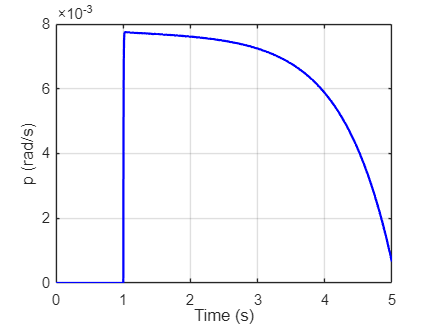

clear
clc


% 0 Controller value

Kp_a = -0.55;

% 1 Run model
open('Roll_Rate_Damper.slx')
out = sim('Roll_Rate_Damper.slx');

% 2 Extract time and signal data
t = out.p.Time;      % Time vector
p = out.p.Data;      % Pitch rate (rad/s)

% 3 Compute step response characteristics

% Plot for verification
figure;
plot(t, p, 'b', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('p (rad/s)');
grid on;


% Compute step response characteristics
info = stepinfo(p, t);
disp('Step Response Characteristics:');

Step Response Characteristics:


disp(info);

         RiseTime: 3.1984e-04
    TransientTime: 4.9847
     SettlingTime: 4.9985
      SettlingMin: 6.6373e-04
      SettlingMax: 0.0077
        Overshoot: 1.0675e+03
       Undershoot: 0
             Peak: 0.0077
         PeakTime: 1.0345

